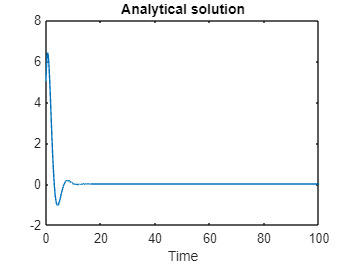

end_time=100;
dt=0.01;
pts=(end_time/dt)+1;

%Spring-mass-damper system
t=linspace(0,end_time,pts);
x0=[5 5];
%Analytical solution
x=zeros([length(t),2]);
c1=x0(1);
c2=(2*x0(2)+c1)/sqrt(3);
x(1,:)=x0;
for i=1:length(t)-1
    co=cos(0.5*sqrt(3)*t(i+1));
    si=sin(0.5*sqrt(3)*t(i+1));
    ep=exp(-t(i+1)/2);
    x(i+1,1)=ep*(c1*co+c2*si);
    x(i+1,2)=0.5*ep*((c2*sqrt(3)-c1)*co-(c1*sqrt(3)+c2)*si);
end
x_og=x;
plot(t,x(:,1));
xlabel('Time');
title('Analytical solution');

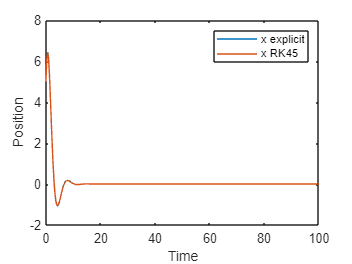


x=zeros([length(t),2]);
x(1,:)=x0;
for i=1:length(t)-1
    x_dot=x(i,2);
    x_ddot=-(x(i,1)+x(i,2));
    x(i+1,2)=x(i,2)+x_ddot*dt;
    x(i+1,1)=x(i,1)+x_dot*dt;
end
x_explicit = x;

x=zeros([length(t),2]);
x(1,:)=x0;
%Implicit Euler
for i=1:length(t)-1
    %x(i+1,:)=(inv([1 dt; dt 1+dt])*(x(i,:))')';
    x_dot=x(i,2);
    x_ddot=-(x(i,1)+x(i,2));
    for j=1:30
    x(i+1,2)=x(i,2)+x_ddot*dt;
    x(i+1,1)=x(i,1)+x_dot*dt;
    x_dot=x(i+1,2);
    x_ddot=-(x(i+1,1)+x(i+1,2));
    end
end
x_implicit=x;
x=zeros([length(t),2]);
x(1,:)=x0;

%Semi-implicit Euler emthod
for i=1:length(t)-1
    x_ddot=-(x(i,1)+x(i,2));
    x(i+1,2)=x(i,2)+dt*x_ddot;
    x_dot=x(i+1,2);
    x(i+1,1)=x(i,1)+dt*x_dot;
end
x_symplectic=x;
%Using ode45
[T,X]=ode45(@rates,[t(1) t(length(t))],x0);
plot(t,x_explicit(:,1));
xlabel('Time');
ylabel('Position');
hold on;
plot(T,X(:,1));
legend('x explicit','x RK45');
hold off;

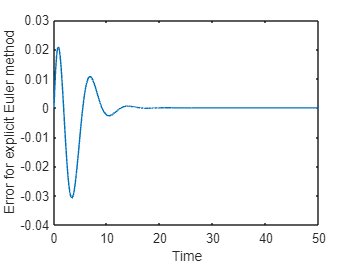

plot(t,x_explicit(:,1)-x_og(:,1));
xlabel('Time');
ylabel('Error for explicit Euler method');
xlim([0,50]);

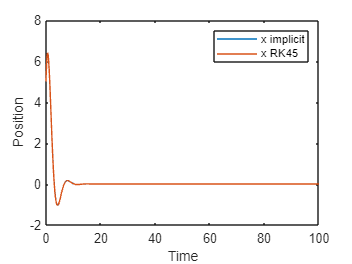



plot(t,x_implicit(:,1));
xlabel('Time');
ylabel('Position');
hold on;
plot(T,X(:,1));
legend('x implicit','x RK45');
hold off;

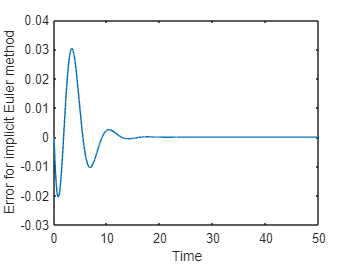

plot(t,x_implicit(:,1)-x_og(:,1));
xlabel('Time');
ylabel('Error for implicit Euler method');
xlim([0,50]);

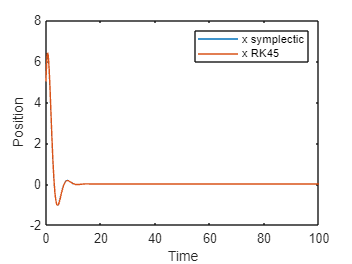



plot(t,x_symplectic(:,1));
xlabel('Time');
ylabel('Position');
hold on;
plot(T,X(:,1));
legend('x symplectic','x RK45');
hold off;

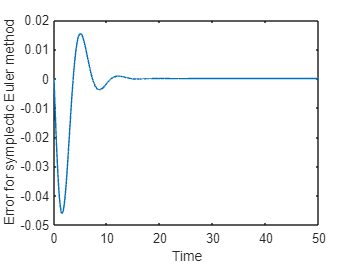

plot(t,x_symplectic(:,1)-x_og(:,1));
xlabel('Time');
ylabel('Error for symplectic Euler method');
xlim([0,50]);

function x_dash=rates(t,x)
    x_dash=[0;0];
    x_dash(1)=x(2);
    x_dash(2)=-(x(1)+x(2));
end